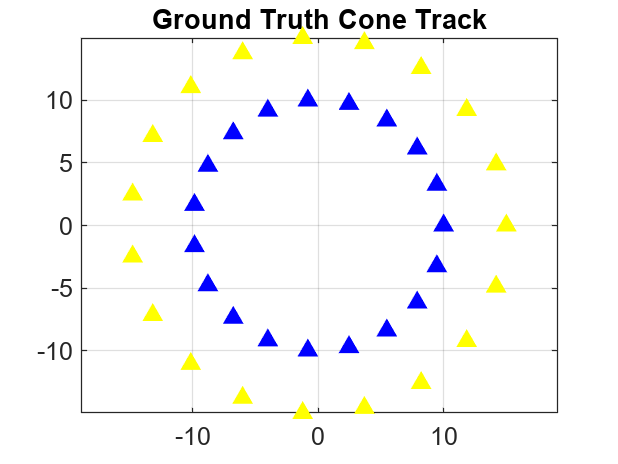

%% 1. Setup the Cone Track (Ground Truth)
clear; clc; close all;

% Define Track as a list of [x, y] points for cones
% Inner loop (Blue) and Outer loop (Yellow)
theta = linspace(0, 2*pi, 20);
inner_radius = 10;
outer_radius = 15;

% Generate Blue Cones (Inner)
blue_cones = [inner_radius * cos(theta)', inner_radius * sin(theta)'];
% Generate Yellow Cones (Outer)
yellow_cones = [outer_radius * cos(theta)', outer_radius * sin(theta)'];

% Combine all cones into one Ground Truth map
mapGroundTruth = [blue_cones; yellow_cones];

% Visualize the Ground Truth Track
figure;
plot(blue_cones(:,1), blue_cones(:,2), 'b^', 'MarkerFaceColor', 'b'); hold on;
plot(yellow_cones(:,1), yellow_cones(:,2), 'y^', 'MarkerFaceColor', 'y');
title('Ground Truth Cone Track');
axis equal; grid on;

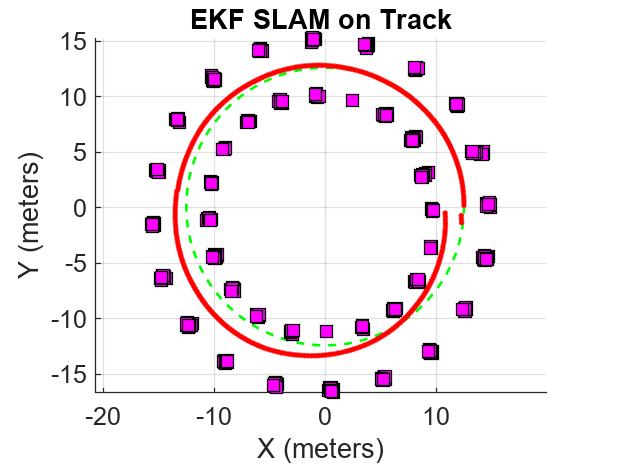


%% 2. Generate Robot Path and Noisy Sensor Data
% We will simulate a robot driving in a circle between the cones
numSteps = 410;
dt = 0.1;
groundTruthState = zeros(numSteps, 3); % [x, y, theta]
currentPose = [12.5, 0, pi/2]; % Start between the rings
measurements = cell(numSteps, 1);
controls = zeros(numSteps, 2); 

% Sensor Parameters
maxRange = 7; % Meters
fov = deg2rad(90); % Field of view

% Simulation Loop
for i = 1:numSteps
    % 1. Move Robot (Circular motion)
    v = 2.0; % 2 m/s
    w = v / 12.5; % Angular velocity to stay in radius 12.5
    
    % Store Control (with noise for the EKF to handle later)
    controls(i,:) = [v + randn*0.1, w + randn*0.05]; 
    
    % Update Ground Truth Pose (Differential Drive Kinematics)
    theta_curr = currentPose(3);
    currentPose(1) = currentPose(1) + v*cos(theta_curr)*dt;
    currentPose(2) = currentPose(2) + v*sin(theta_curr)*dt;
    currentPose(3) = currentPose(3) + w*dt;
    groundTruthState(i,:) = currentPose;
    
    % 2. Simulate Lidar/Camera detecting Cones
    % Find cones within range and FOV
    visibleLandmarks = [];
    for j = 1:size(mapGroundTruth, 1)
        dx = mapGroundTruth(j,1) - currentPose(1);
        dy = mapGroundTruth(j,2) - currentPose(2);
        dist = sqrt(dx^2 + dy^2);
        angle_to_landmark = atan2(dy, dx) - currentPose(3);
        
        % Normalize angle to -pi to pi
        angle_to_landmark = atan2(sin(angle_to_landmark), cos(angle_to_landmark));
        
        if dist < maxRange && abs(angle_to_landmark) < fov/2
            % Add noise to measurement (Sensor Noise)
            measDist = dist + randn * 0.1; 
            measAng = angle_to_landmark + randn * 0.02;
            % Store measurement [Range, Bearing]
            visibleLandmarks = [visibleLandmarks; measDist, measAng]; 
        end
    end
    measurements{i} = visibleLandmarks;
end

%% 3. Run EKF SLAM
% Initialize EKF Object
initialState = [12.5, 0, pi/2]; 

ekf_result = run_ekf_simulation(initialState, controls, measurements, dt, groundTruthState);


% Calculate and Print Error
calculate_simulation_error(ekf_result, groundTruthState, mapGroundTruth);


       EKF SIMULATION ERROR METRICS       
Final Robot Position Error:  4.1323 meters
Map Alignment RMSE:          1.2416 meters


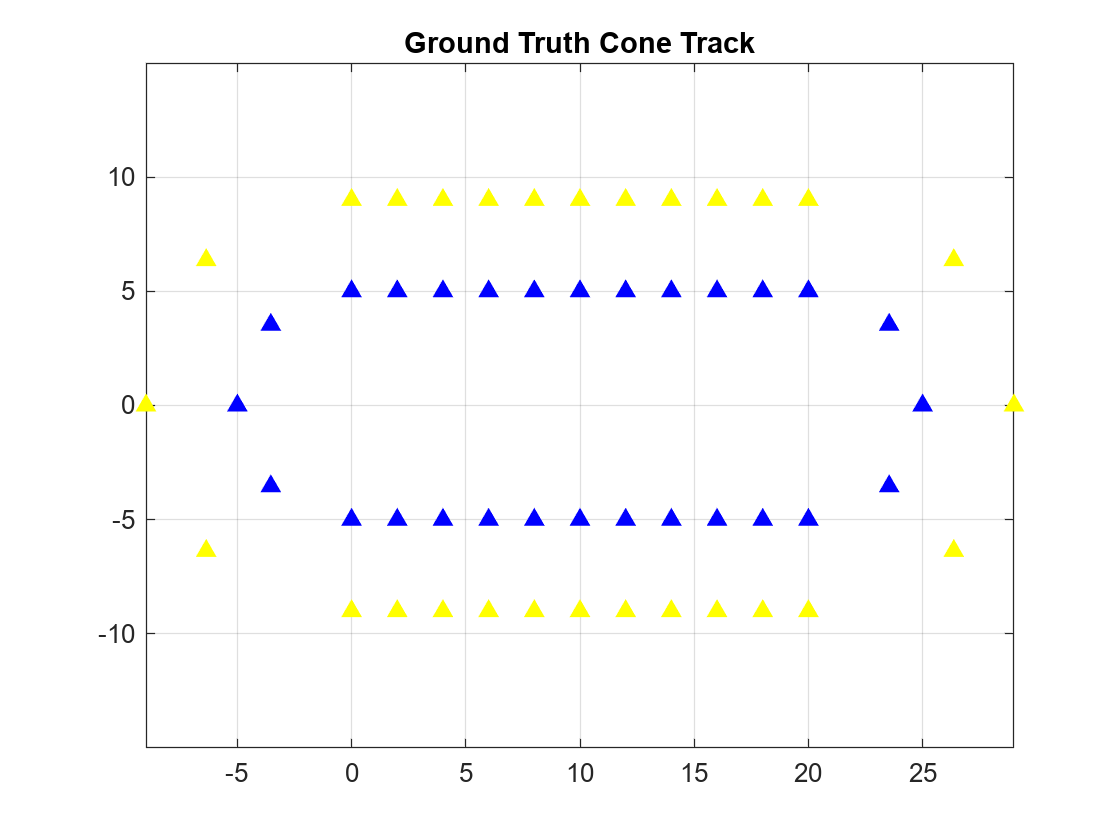

%% 1. Setup the Smaller "Stadium" Cone Track
clear; clc; close all;

% Reduced Parameters for Speed
R_inner = 5;       % Smaller turn radius
R_outer = 9;       % Tighter track width
straight_len = 20; % Shorter straight sections
cone_spacing = 2.0; 

% Generate Inner Cones
% 1. Top Straight (Left to Right)
x_straight = 0:cone_spacing:straight_len;
inner_top = [x_straight', repmat(R_inner, length(x_straight), 1)];

% 2. Right Curve (180 degrees)
theta = linspace(-pi/2, pi/2, 5); % Fewer cones for speed
inner_right = [straight_len + R_inner*cos(theta)', R_inner*sin(theta)'];

% 3. Bottom Straight (Right to Left)
inner_bottom = [flip(x_straight)', repmat(-R_inner, length(x_straight), 1)];

% 4. Left Curve (180 degrees)
theta_left = linspace(pi/2, 3*pi/2, 5);
inner_left = [R_inner*cos(theta_left)', R_inner*sin(theta_left)'];

% Combine Inner Loop
blue_cones = [inner_top; inner_right; inner_bottom; inner_left];

% Generate Outer Cones
outer_top = [x_straight', repmat(R_outer, length(x_straight), 1)];
outer_right = [straight_len + R_outer*cos(theta)', R_outer*sin(theta)'];
outer_bottom = [flip(x_straight)', repmat(-R_outer, length(x_straight), 1)];
outer_left = [R_outer*cos(theta_left)', R_outer*sin(theta_left)'];

yellow_cones = [outer_top; outer_right; outer_bottom; outer_left];
mapGroundTruth = [blue_cones; yellow_cones];

% Visualize Track
figure;
plot(blue_cones(:,1), blue_cones(:,2), 'b^', 'MarkerFaceColor', 'b'); hold on;
plot(yellow_cones(:,1), yellow_cones(:,2), 'y^', 'MarkerFaceColor', 'y');
title('Ground Truth Cone Track');
axis equal; grid on;

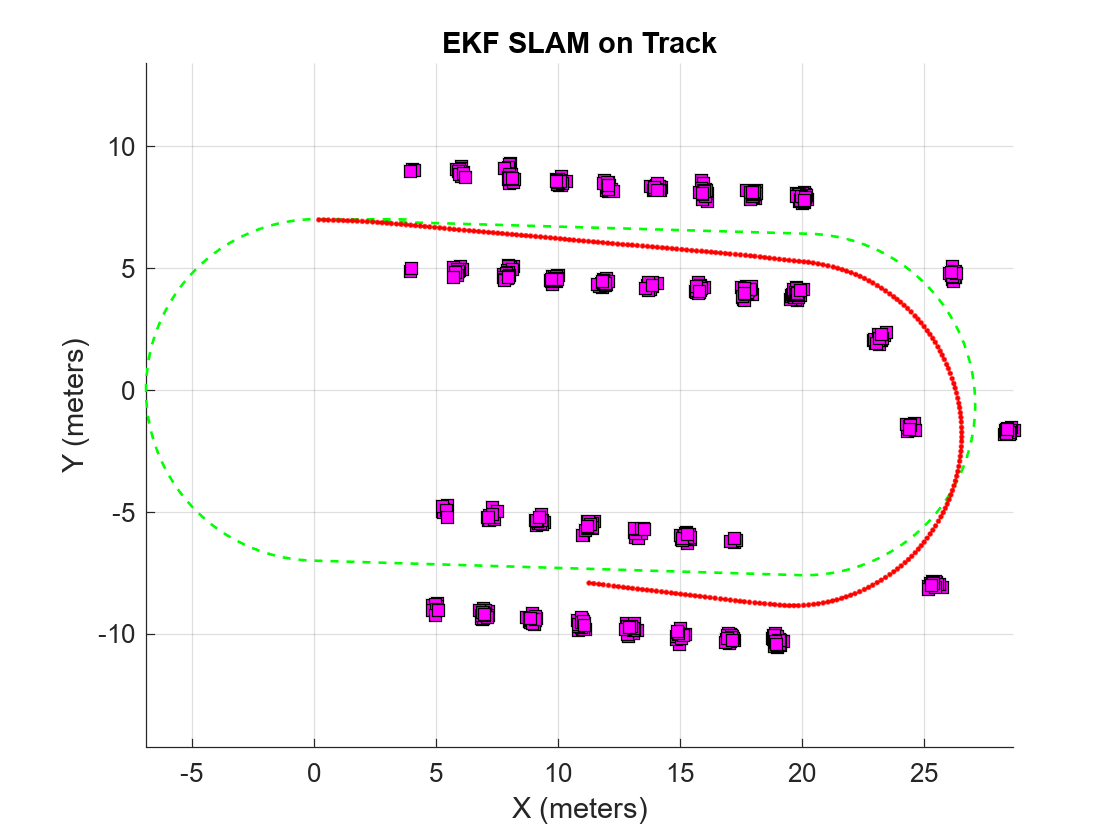


%% 2. Generate Robot Path
dt = 0.1;
R_path = (R_inner + R_outer) / 2; % Middle of track (Radius 7)
v_target = 2.0; 

% Automatic Step Calculation based on smaller track
total_dist = (2 * straight_len) + (2 * pi * R_path);
total_time = total_dist / v_target;
numSteps = ceil(total_time / dt) + 20; 

groundTruthState = zeros(numSteps, 3); 
measurements = cell(numSteps, 1);
controls = zeros(numSteps, 2); 

% Start Pose
currentPose = [0, R_path, 0]; 

% Sensor Config
maxRange = 8; 
fov = deg2rad(90); 

for i = 1:numSteps
    % Motion Logic
    x = currentPose(1); y = currentPose(2);
    
    if (x < straight_len && x > 0 && y > 0) % Top Straight
        v = v_target; w = 0;
    elseif (x < straight_len && x > 0 && y < 0) % Bottom Straight
        v = v_target; w = 0;
    else % Curves
        v = v_target;
        w = -v / R_path; 
    end
    
    controls(i,:) = [v + randn*0.1, w + randn*0.05]; 
    
    % Update Ground Truth
    theta_curr = currentPose(3);
    currentPose(1) = currentPose(1) + v*cos(theta_curr)*dt;
    currentPose(2) = currentPose(2) + v*sin(theta_curr)*dt;
    currentPose(3) = currentPose(3) + w*dt;
    groundTruthState(i,:) = currentPose;
    
    % Sensor Simulation 
    visibleLandmarks = [];
    for j = 1:size(mapGroundTruth, 1)
        dx = mapGroundTruth(j,1) - currentPose(1);
        dy = mapGroundTruth(j,2) - currentPose(2);
        dist = sqrt(dx^2 + dy^2);
        
        % Check distance first (fastest check)
        if dist < maxRange
            angle_to_landmark = atan2(dy, dx) - currentPose(3);
            angle_to_landmark = atan2(sin(angle_to_landmark), cos(angle_to_landmark));
            
            if abs(angle_to_landmark) < fov/2
                measDist = dist + randn * 0.1; 
                measAng = angle_to_landmark + randn * 0.02;
                visibleLandmarks = [visibleLandmarks; measDist, measAng]; 
            end
        end
    end
    measurements{i} = visibleLandmarks;
end

%% 3. Run EKF SLAM (Optimized)
initialState = [0, R_path, 0]; 

ekf_result = run_ekf_simulation(initialState, controls, measurements, dt, groundTruthState);


calculate_simulation_error(ekf_result, groundTruthState, mapGroundTruth);

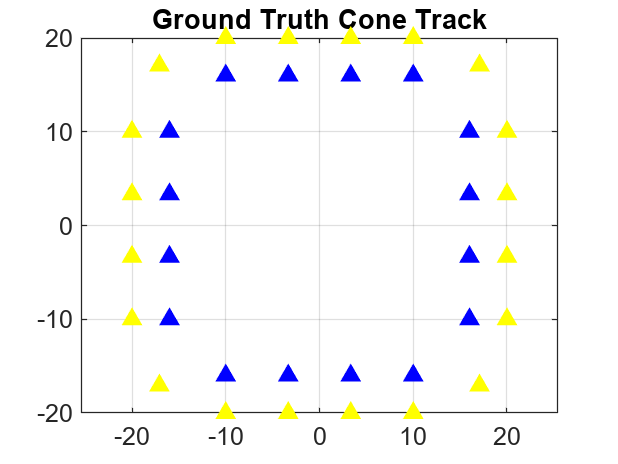

%% 1. Setup the "Rounded Square" Track (Fully Populated)
clear; clc; close all;

% Track Dimensions
side_len = 20;      % Length of straight sides (between corner centers)
corner_radius = 6;  % Radius of inner corners
cone_spacing = 5; % Spacing for cones

% Generates points from A to B with specific spacing
gen_line = @(p1, p2, sp) [linspace(p1(1), p2(1), ceil(norm(p2-p1)/sp))', ...
                          linspace(p1(2), p2(2), ceil(norm(p2-p1)/sp))'];

% Generate Inner Loop (Radius 6)
% Centers of the 4 corners
tr_cen = [side_len/2, side_len/2];   % Top-Right
tl_cen = [-side_len/2, side_len/2];  % Top-Left
bl_cen = [-side_len/2, -side_len/2]; % Bottom-Left
br_cen = [side_len/2, -side_len/2];  % Bottom-Right

% Corners
c_tr_in = gen_corner(tr_cen, corner_radius, 0, pi/2, 2);     % Top-Right
c_tl_in = gen_corner(tl_cen, corner_radius, pi/2, pi, 2);    % Top-Left
c_bl_in = gen_corner(bl_cen, corner_radius, pi, 3*pi/2, 2);  % Bottom-Left
c_br_in = gen_corner(br_cen, corner_radius, 3*pi/2, 2*pi, 2);% Bottom-Right

% Straights (Connecting the corners)
% Top Straight (connects TR end to TL start)
s_top_in = gen_line([side_len/2, side_len/2 + corner_radius], ...
                    [-side_len/2, side_len/2 + corner_radius], cone_spacing);
% Left Straight
s_left_in = gen_line([-side_len/2 - corner_radius, side_len/2], ...
                     [-side_len/2 - corner_radius, -side_len/2], cone_spacing);
% Bottom Straight
s_bot_in = gen_line([-side_len/2, -side_len/2 - corner_radius], ...
                    [side_len/2, -side_len/2 - corner_radius], cone_spacing);
% Right Straight
s_right_in = gen_line([side_len/2 + corner_radius, -side_len/2], ...
                      [side_len/2 + corner_radius, side_len/2], cone_spacing);

blue_cones = [c_tr_in; s_top_in; c_tl_in; s_left_in; c_bl_in; s_bot_in; c_br_in; s_right_in];

% Generate Outer Loop (Radius 10)
R_out = corner_radius + 4; % 4 meters wide track

% Corners
c_tr_out = gen_corner(tr_cen, R_out, 0, pi/2, 3);
c_tl_out = gen_corner(tl_cen, R_out, pi/2, pi, 3);
c_bl_out = gen_corner(bl_cen, R_out, pi, 3*pi/2, 3);
c_br_out = gen_corner(br_cen, R_out, 3*pi/2, 2*pi, 3);

% Straights
s_top_out = gen_line([side_len/2, side_len/2 + R_out], ...
                     [-side_len/2, side_len/2 + R_out], cone_spacing);
s_left_out = gen_line([-side_len/2 - R_out, side_len/2], ...
                      [-side_len/2 - R_out, -side_len/2], cone_spacing);
s_bot_out = gen_line([-side_len/2, -side_len/2 - R_out], ...
                     [side_len/2, -side_len/2 - R_out], cone_spacing);
s_right_out = gen_line([side_len/2 + R_out, -side_len/2], ...
                       [side_len/2 + R_out, side_len/2], cone_spacing);

yellow_cones = [c_tr_out; s_top_out; c_tl_out; s_left_out; c_bl_out; s_bot_out; c_br_out; s_right_out];

mapGroundTruth = [blue_cones; yellow_cones];

% Visualize Track
figure;
plot(blue_cones(:,1), blue_cones(:,2), 'b^', 'MarkerFaceColor', 'b'); hold on;
plot(yellow_cones(:,1), yellow_cones(:,2), 'y^', 'MarkerFaceColor', 'y');
title('Ground Truth Cone Track');
axis equal; grid on;

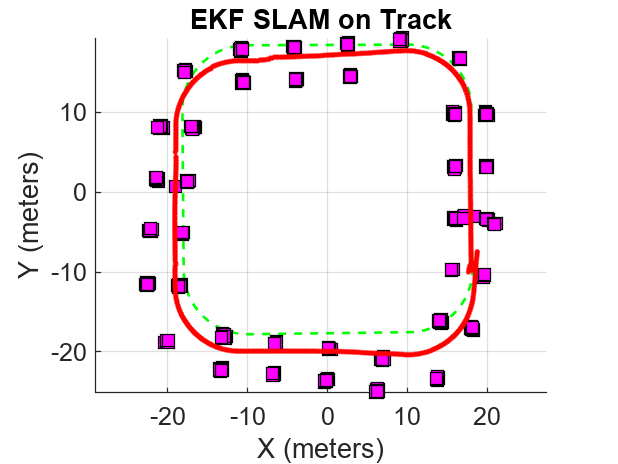


%% 2. Generate Robot Path
dt = 0.1;
v_target = 2.0; 
R_path = (corner_radius + R_out) / 2; % Middle path

% Calculate Steps: 4 Straights + 4 Quarter-Circles
dist_straight = side_len * 4;
dist_curved = 2 * pi * R_path;
total_time = (dist_straight + dist_curved) / v_target;
numSteps = ceil(total_time / dt) + 40;

groundTruthState = zeros(numSteps, 3); 
measurements = cell(numSteps, 1);
controls = zeros(numSteps, 2); 

% Start Pose: Middle of Right Straight, heading North
% (Start coordinate matches the geometry of s_right_in/out)
currentPose = [side_len/2 + R_path, -side_len/2, pi/2]; 

% Sensor Config
maxRange = 7; 
fov = deg2rad(90); 

% State Machine for Square Logic
% 1: Straight North, 2: Turn Left, 3: Straight West, 4: Turn Left...
mode = 1; 
timer = 0;
straight_time = side_len / v_target;
turn_time = (0.5 * pi * R_path) / v_target;

for i = 1:numSteps
    if mode == 1 || mode == 3 || mode == 5 || mode == 7 || mode == 9 % Straights
        v = v_target; w = 0;
        if timer > straight_time
            mode = mode + 1; timer = 0;
        end
    else % Turns (90 degree left turns)
        v = v_target;
        w = v / R_path; 
        if timer > turn_time
            mode = mode + 1; timer = 0;
        end
    end
    timer = timer + dt;
    
    controls(i,:) = [v + randn*0.1, w + randn*0.05]; 
    
    theta_curr = currentPose(3);
    currentPose(1) = currentPose(1) + v*cos(theta_curr)*dt;
    currentPose(2) = currentPose(2) + v*sin(theta_curr)*dt;
    currentPose(3) = currentPose(3) + w*dt;
    groundTruthState(i,:) = currentPose;
    
    visibleLandmarks = [];
    for j = 1:size(mapGroundTruth, 1)
        dx = mapGroundTruth(j,1) - currentPose(1);
        dy = mapGroundTruth(j,2) - currentPose(2);
        dist = sqrt(dx^2 + dy^2);
        if dist < maxRange
            angle_to_landmark = atan2(dy, dx) - currentPose(3);
            angle_to_landmark = atan2(sin(angle_to_landmark), cos(angle_to_landmark));
            if abs(angle_to_landmark) < fov/2
                measDist = dist + randn * 0.1; 
                measAng = angle_to_landmark + randn * 0.02;
                visibleLandmarks = [visibleLandmarks; measDist, measAng]; 
            end
        end
    end
    measurements{i} = visibleLandmarks;
end

%% 3. Run EKF SLAM
initialState = [side_len/2 + R_path, -side_len/2, pi/2]; 

ekf_result = run_ekf_simulation(initialState, controls, measurements, dt, groundTruthState);


calculate_simulation_error(ekf_result, groundTruthState, mapGroundTruth);


       EKF SIMULATION ERROR METRICS       
Final Robot Position Error:  6.7172 meters
Map Alignment RMSE:          2.6677 meters
